# bisectionAlgorithm

Calcola lo zero di una funzione in un dato intervallo utilizzando l'algoritmo della bisezione. [1] 

## Sintassi

x = bisectionAlgorithm(f,x0)

Error using bisectionAlgorithm (line 71)
La funzione deve assumere valori discordi agli estremi dell'intervallo x0 oppure uno di essi deve annullare la funzione.

x = bisectionAlgorithm(f,x0,TOL)
x = bisectionAlgorithm(f,x0,TOL,NMAX)

[x, output] = bisectionAlgorithm()

[x, output, graf] = bisectionAlgorithm()

## Descrizione

- x = bisectionAlgorithm(f, x0) cerca di trovare un punto x in cui  f(x)=0 a meno di TOLF, all'interno dell'intervallo specificato da x0. La soluzione si trova nel punto in cui f(x) cambia segno : gli estremi dell'intervallo devono essere necessariamente discordi.

- x = bisectionAlgorithm(f, x0,TOL) usa TOL per determinare l'accuratezza della soluzione. Se non specificato, TOL=eps.

- x = bisectionAlgorithm(f, x0,TOL,NMAX) usa TOL per determinare l'accuratezza della soluzione e NMAX per individuare il numero massimo di iterazioni che l'algoritmo può compiere. Se non specificati, TOL=eps, NMAX=500.

- [x , output] = bisectionAlgorithm(___) restituisce, oltre alla soluzione, una struttura output che contiene due campi: fx con il valore della funzione in x, niter con il numero di iterazioni eseguite  dall'algoritmo per individuare la soluzione con quel grado di accuratezza.

- [x , output, graf] = bisection_algorithm(___) restituisce anche una variabile di tipo string, che indica l'avvenuto plotting del grafico funzione e dello zero trovato.

## Esempi

**Calcolo dello zero a  partire da un intervallo **

Calcola lo zero della funzione` f(x) = sin(x)` nell'intervallo `[3,6]``.`

f = @(x)(sin(x)); % funzione
x0 = [3 6]; % intervallo iniziale
x = bisectionAlgorithm(f,x0)

x =    3.141592653589793


**Calcola lo zero specificando accuratezza e numero massimo di iterazioni**

Calcola lo zero della funzione`  f(x) = sin(x)` nell'intervallo `[3,6],` con `TOL=1e-3 `e` NMAX=50`

f = @(x)sin(x); % funzione
x0 = [3 6]; % intervallo iniziale
x = bisectionAlgorithm(f,x0, 1e-3, 50)

x =    3.143554687500000


**Calcola lo zero con tutti i parametri di output**

Calcola lo zero della funzione`  f(x) = sin(x)` nell'intervallo `[3,6] `ottenendo la struttura contenente il valore di `f(x) `e il numero di iterazioni che l'algoritmo ha eseguito, e il grafico di `f `nell'intervallo` x0`.

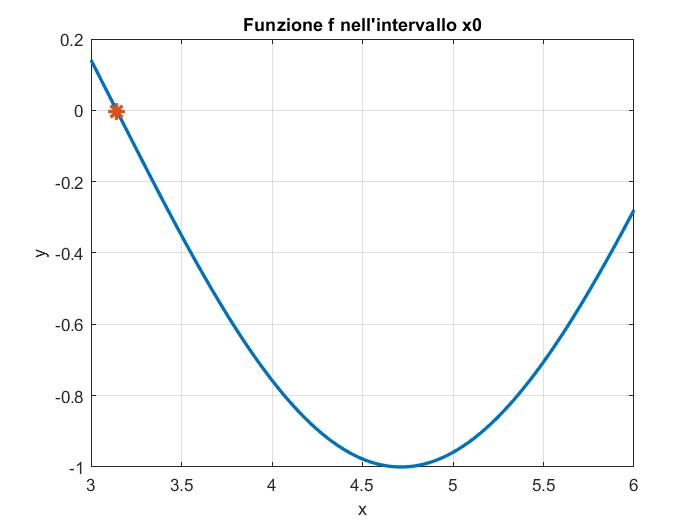

x =    3.143554687500000


output = struct with fields:
    niter: 10
       fx: -0.001962032651374


graf = 'Plotted'

f = @(x)sin(x); % funzione
x0 = [3 6]; % intervallo iniziale
[x output graf]= bisectionAlgorithm(f,x0)

## Argomenti di input

**f - Funzione da risolvere **`( function handle )`

Funzione di cui si vuole calcolare lo zero, specificata come handle di funzione o con il nome della funzione. `bisectionAlgorithm` risolve f(x)=0. Per risolvere un'equazione del tipo f(x)=c(x), è possibile utilizzare un handle definito come f2=@(x)(f(x)-c(x)).

**Esempio:** @sin

**Esempio:** @myFunction

**Esempio:** @(x)(x^2 - 2)

**Data Types:** `function_handle`

**x0 - Intervallo iniziale**` ( array di 2 elementi )`

Intervallo iniziale, definito da due numeri reali . `bisectionAlgorithm` verifica che  f(x0(0)) e f(x0(1)) abbiano segni discordi, e mostra un errore se ciò non è verificato.Successivamente, restringe iterativamente l'intervallo per raggiungere la soluzione. L'intervallo x0 deve essere finito: non può contenere  .

**Esempio:** [2 17]

**Data Types: **`double`

**TOL - Accuratezza ( **`double `**)**

Valore di tolleranza per x. Il valore di default è eps, 2.2204e-16.

Parametro facoltativo. 

**Data Types: **`double`

**NMAX - Limite iterazioni ( **`integer `**)**

Numero massimo di iterazioni. Il valore di default è 500.

Parametro facoltativo. 

**Data Types:** `integer`

## Argomenti di output

**x - Valore dell'approssimazione dello zero **`( real scalar ) `

Valore dell'approssimazione dello zero, restituita come uno scalare.

**output - informazioni di output **`( struct )`

Informazioni aggiuntive sul risultato ottenuto. I campi della struttura sono:

- `fx:` valore assunto dalla funzione `f` nel punto `x;`

- `niter:` numero di iterazioni compiute per ottenere il risultato con la precisione richiesta.

**graf - stampa del grafico**` ( string )`

Se questo parametro è richiesto come output, verrà generato un grafico della funzione `f` nell'intervalllo lo `x0 `. Mostrando inoltre il punto in cui è stato individuato lo zero della funzione. La variabile `graf` assume il valore `'Plotted'`.

## Riferimenti

[1] Corliss, George, "Which root does the bisection algorithm find?", SIAM Review, 1977

## Autore

Gabriele Previtera